# **EEE-3102: Numerical Technique Laboratory**

# **Lab-07: Determination of the solution of differential equations.**

#### Exercise-1: Find the solution of the following ODE and plot the result for a suitable range of t. $\frac{d\;y}{d\;t}+4y\left(t\right)=e^{-t}$ with y(0)=1.

syms y(t)
Dy = diff(y);
ode = diff(y,t,1)+4*y == exp(-t) ;
cond1 = y(0) == 1;
yS = dsolve(ode,cond1);
yS = simplify(yS)

$$yS = \frac{{\mathrm{e}}^{-t}}{3}+\frac{2\,{\mathrm{e}}^{-4\,t}}{3}$$

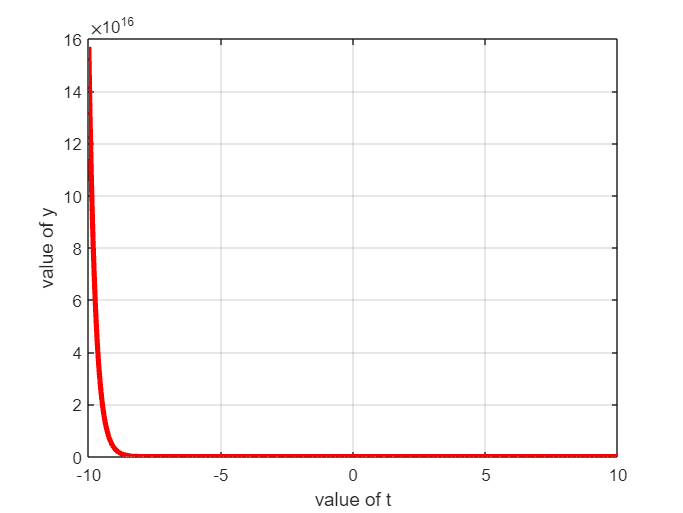


t = linspace(-10,10,1000);
y=(exp(-t)/3)+(2*exp(-4*t))/3;


plot(t,y,'r','LineWidth',3)
xlabel('value of t')
ylabel('value of y')
grid on

#### Exercise-2: Find the solution of the following differential equation and plot the result for a suitable range of x. $2x^2 \frac{d^2 y}{dx^2 }+3x\frac{d\;y}{d\;x}-y=0$ with $y1=1$ and $y^{\prime } \left(1\right)=1\ldotp$

clc; close all; clear all;
syms y(x)
Dy = diff(y);
ode = 2*x^2*diff(y,x,2) + 3*x*diff(y,x,1)-y == 0 ;
cond1 = y(1) == 1;
cond2 = Dy(1) == 1;
conds = [cond1 cond2];
yS = dsolve(ode,conds);
yS = simplify(yS)

$$yS = \frac{4\,\sqrt{x}}{3}-\frac{1}{3\,x}$$


x = -0.2:0.001:0.2; 
y =(4*x.^(1/2))/3 - 1./(3*x); 
plot(x,y,'r','linewidth',2) 

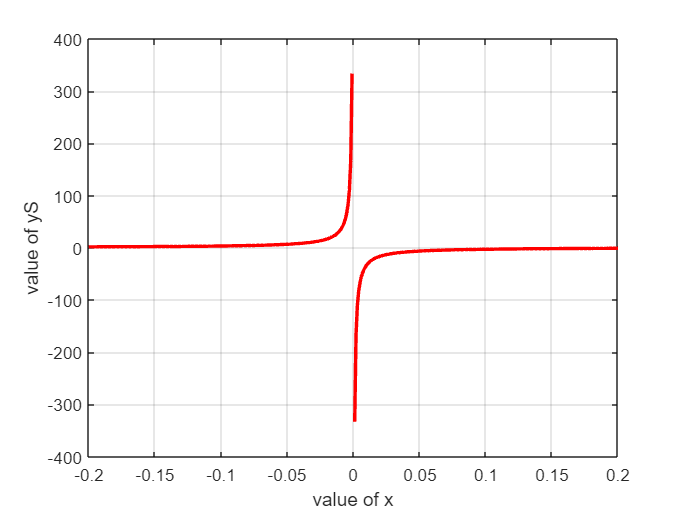

xlabel('value of x') 
ylabel('value of yS') 
grid on